# Práctica 5. Sistemas de sonido espacial

Problema de trigonometría

WFS

Tenemos una serie de altavoces colocados en fila

También disponemos de la fuente virtual a analizar, colocada a una cierta distancia y un cierto ángulo de la serie de altavoces

También tenemos el punto de serie colocado más abajo. Para sentirse rodeado, como si fuese real.

La práctica está muy guiada, paso a paso. (Dibujo en la hoja del enunciado de la práctica uwu)

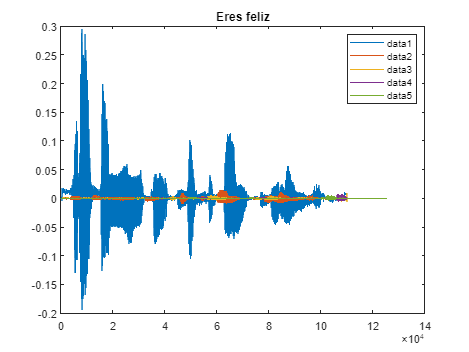

Soy feliz

x = ['TDA.mp3'];
N = 5;
gap = 30;
P_inicial = [1 ,1];
P_final = [1, 10];
qn = wfs(x, N, gap, P_inicial, P_final);

En principio crearemos una función qn=wfs(x, N, gap, P_inicial, P_final)

x -> La señal

N -> Nº altavoces

gap -> Separación entre altavoces

P_inicial -> Dónde empieza la señal

P_final -> Dónde termina la señal

Cuanto tiempo estará desplazandose el sonido? Lo que dure

qn, contiene las señales de driving de cada altavoz

Nos dan todo pasito a pasito

1.- Determinar las posiciones de las fuentes secundarias (la primera siempre en 0,0), almacena las posiciones en una única matriz (x,y). ----> X positivo             (pa arriba) Y positivo

La difilcultad está en, los altavoces, matriz de dos columnas. Vector de los Altavoces

0     0

gap 0

.........

function qn = wfs(x,N,gap,p_ini,p_fin)
[x,fs] = audioread(x);

Vector_Altavoces=zeros(N,2);

 for i = 1 : N
        %Cada altavoz esta separado uno del otro por la distancia gap.
        Vector_Altavoces(i, 1) = (i - 1)*gap;
end

% gap_aux = gap;
% 
% for i=2:N
%     for j=1:2
%         if j==1
%             Vector_Altavoces(i,j) = gap_aux;
%         elseif j==2
%             Vector_Altavoces(i,j) = 0;
%         end
%     end
%             gap_aux=gap_aux+gap;
% end

2.- Determinar la trayectoria que debe seguir la fuente muestra a muestra. Almacenar en una única matriz usando 2 columnas. Para obtener la trayectoria del sonido, hacer un vector de X muestras, que vaya desde Xo, Yo hasta Xf, Yf. Vector del Sonido TRIGONOMETRIA PURA Y DURA

Long_Sonido = length(x);

X_ini = p_ini(1);
Y_ini = p_ini(2);

X_fin = p_fin(1);
Y_fin = p_fin(2);

L = sqrt(((X_fin-X_ini)^2)+((Y_fin+Y_ini)^2));
Delta = L/Long_Sonido;
Alpha = atan((X_fin-X_ini)/(Y_fin-Y_ini));

DeltaX = Delta*sin(Alpha);
DeltaY = Delta*cos(Alpha);

Trayectoria=zeros(Long_Sonido,2);

for i=1:Long_Sonido
    Trayectoria(i,1) = X_ini + (DeltaX*i);
    Trayectoria(i,2) = Y_ini + (DeltaY*i);
end

3.- Determinar la distancia Rm entre cada punto de la trayectoria para cada altavoz. Cada punto tiene una distancia a cada altavoz, por lo que hay que hacer un puñado de calculos, un coñazo. PITAGORAS!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!

d=sqrt((X1-Xini)^2 + (Y1-Yini)^2)

X1 -> Puntos

Xini -> Altavoces

Distancia=zeros(Long_Sonido,N);

for n=1:N
    for i=1:Long_Sonido
        
    Distancia(i,n)=sqrt(((Vector_Altavoces(n,1)-Trayectoria(i,1)).^2) + (Trayectoria(i,2)).^2 );
        
    end
end

4.- Determinar el tiempo tn, que tarda el sonido en recorder a cada uno de los punto anteriores. Con la distancia y la velocidad del sonido, puedo calcular el tiempo que tarda, sencillo

c = 340; %Velocidad del sonido

Tiempo = zeros(Long_Sonido,N);
for n=1:N
    for i=1:Long_Sonido
        Tiempo(i,n) = Distancia(i,n)/c;
    end
end

5.- Determinar el angulo TETA, entre la posición de cada punto y de cada altavoz

for i=1:(Long_Sonido-1)
    for j=1:N

        Dif(i,j) = abs(Trayectoria(i,1)-Vector_Altavoces(j,1));
        Ang(i,j) = asin(Dif(i,j)/Distancia(i,j));

    end
end

6.- Determinar el valor de So para cada posición de la trayectoria, So es Y

for n=1:N
    for i=1:Long_Sonido

        Vertical(i,n) = Trayectoria(i,2);

    end
end

7.- Fijar Ro como una cuarta parte del ancho del array.

R0 = (3/4)*N*gap;

8.- Aplicar la formula que aparece aquí

Determinaremos la señal driving para cada altavoz

K indicará la muestra que estamos seleccionando


Long_Sonido_New = Long_Sonido + round(max(max(Tiempo))*fs);

qn=zeros(Long_Sonido_New,N);

for n = 1:N
    for i=1:Long_Sonido-1

        qn(i,n) = sqrt((R0/(R0+Vertical(i,n)))).*(1/sqrt(Distancia(i,n))).*cos(Ang(i,n)).*x(i + (floor(fs*(Tiempo(i,n)))));
        
    end
end


9.- Ser feliz

plot(qn)
legend
title('Eres feliz');
fprintf("Soy feliz");

10.- Fin

end